# Signals in time and frequency domain

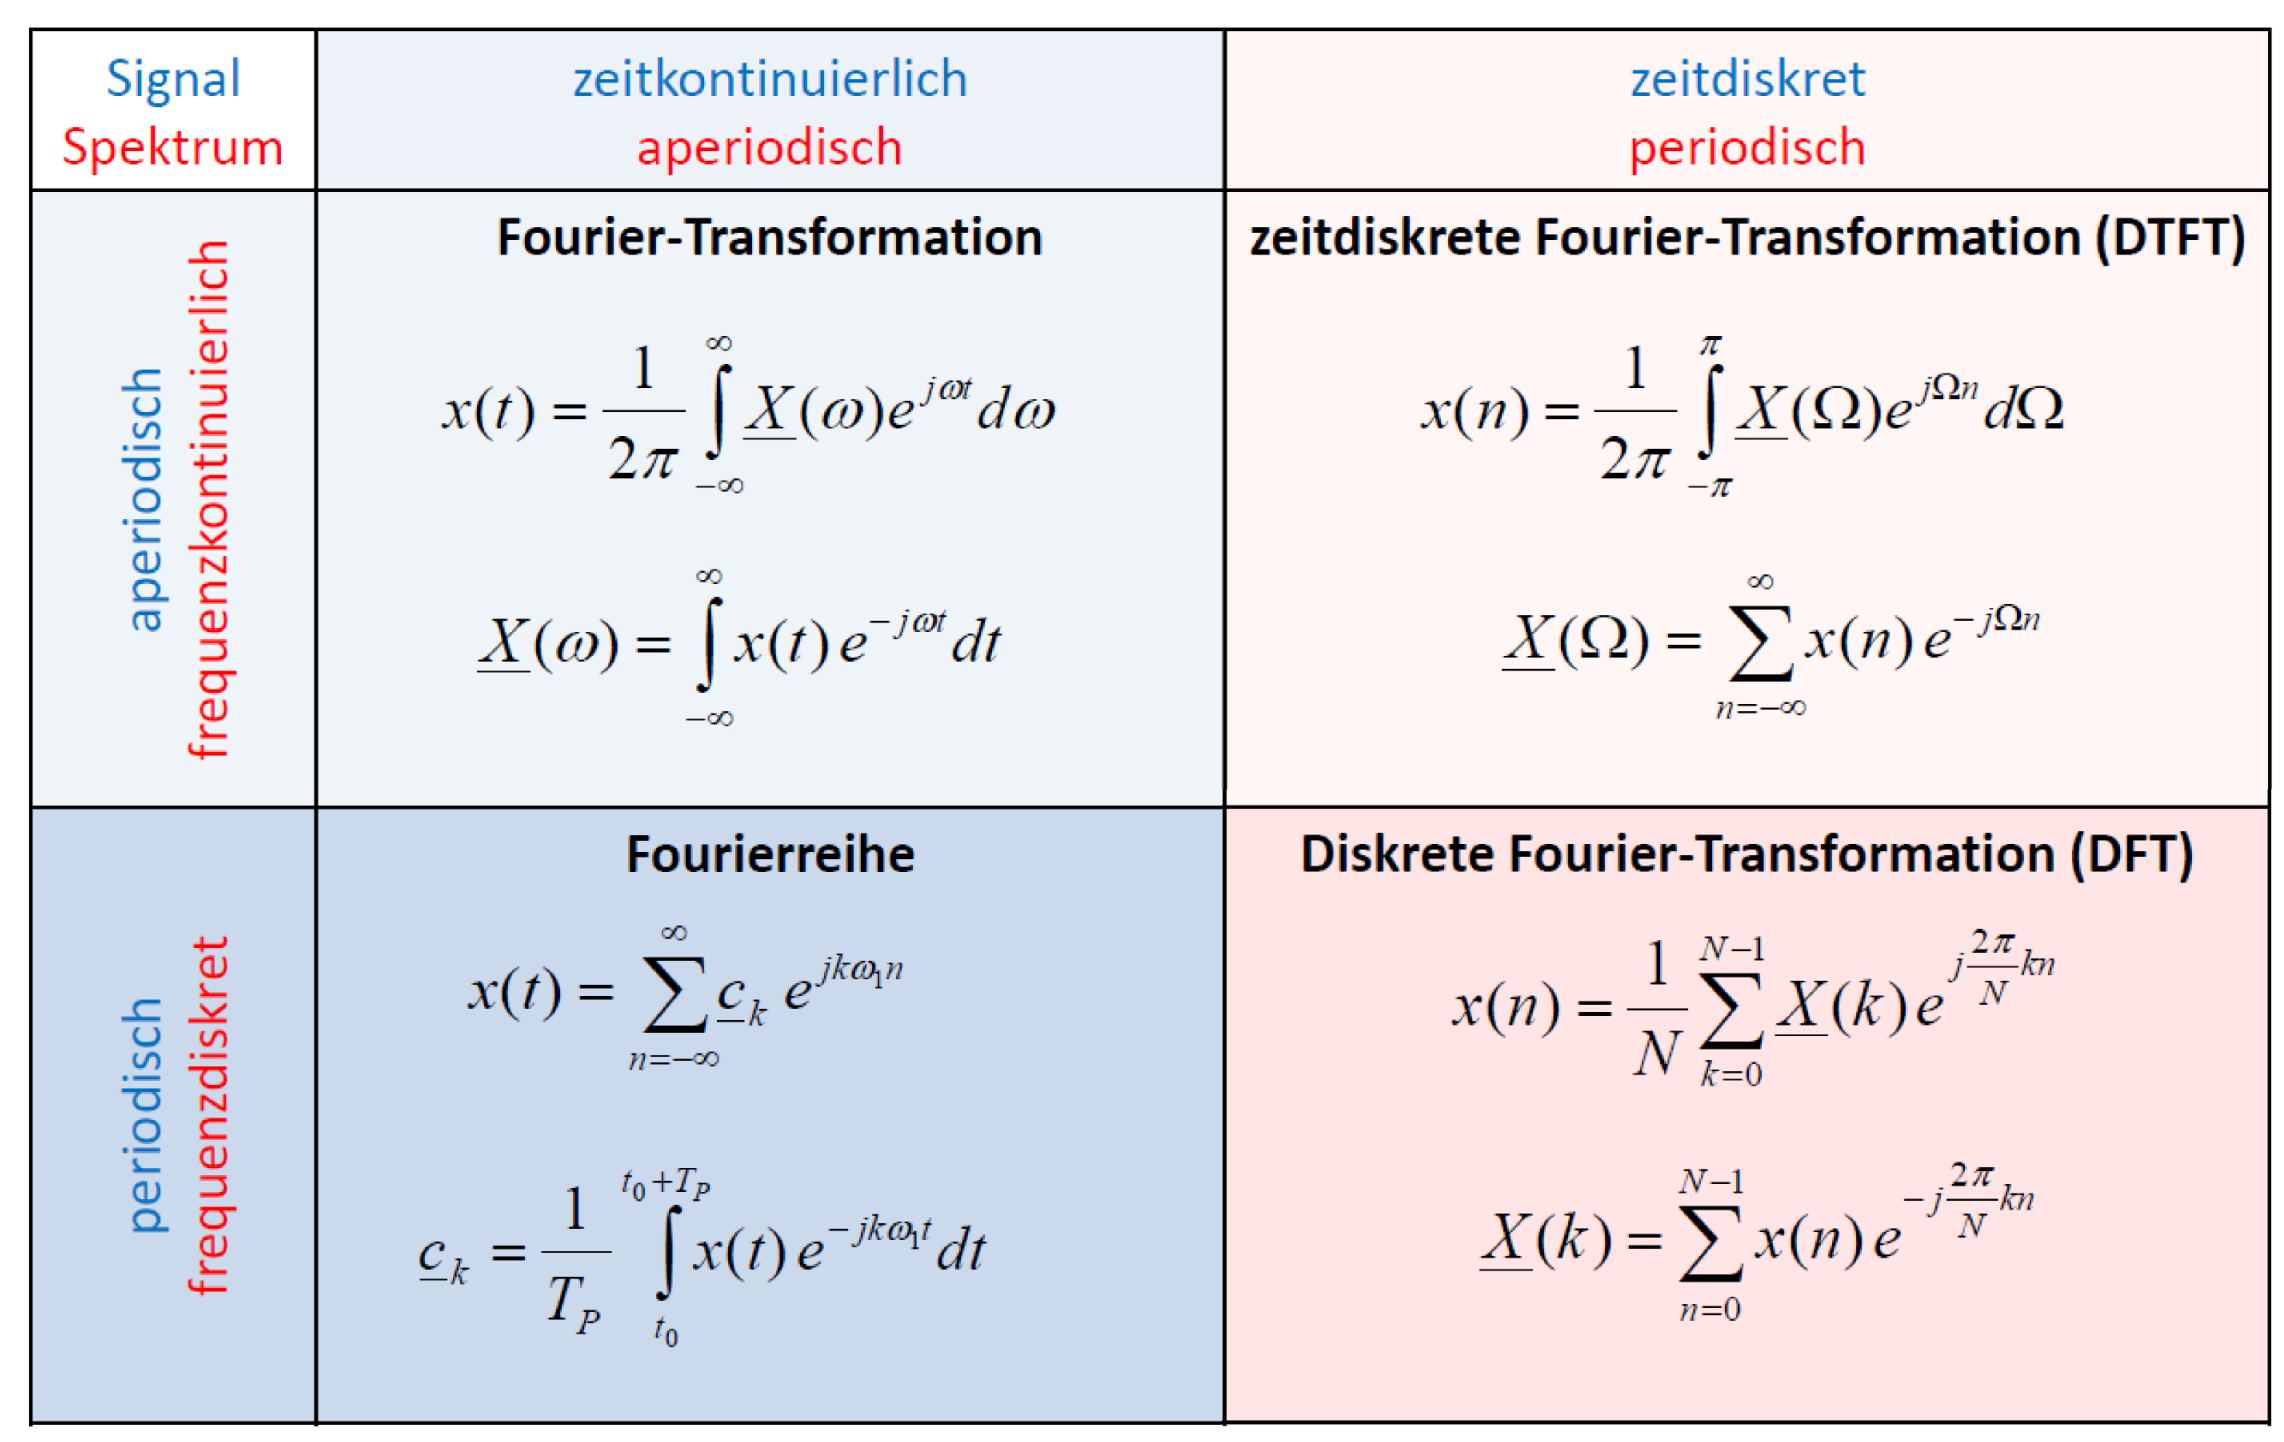

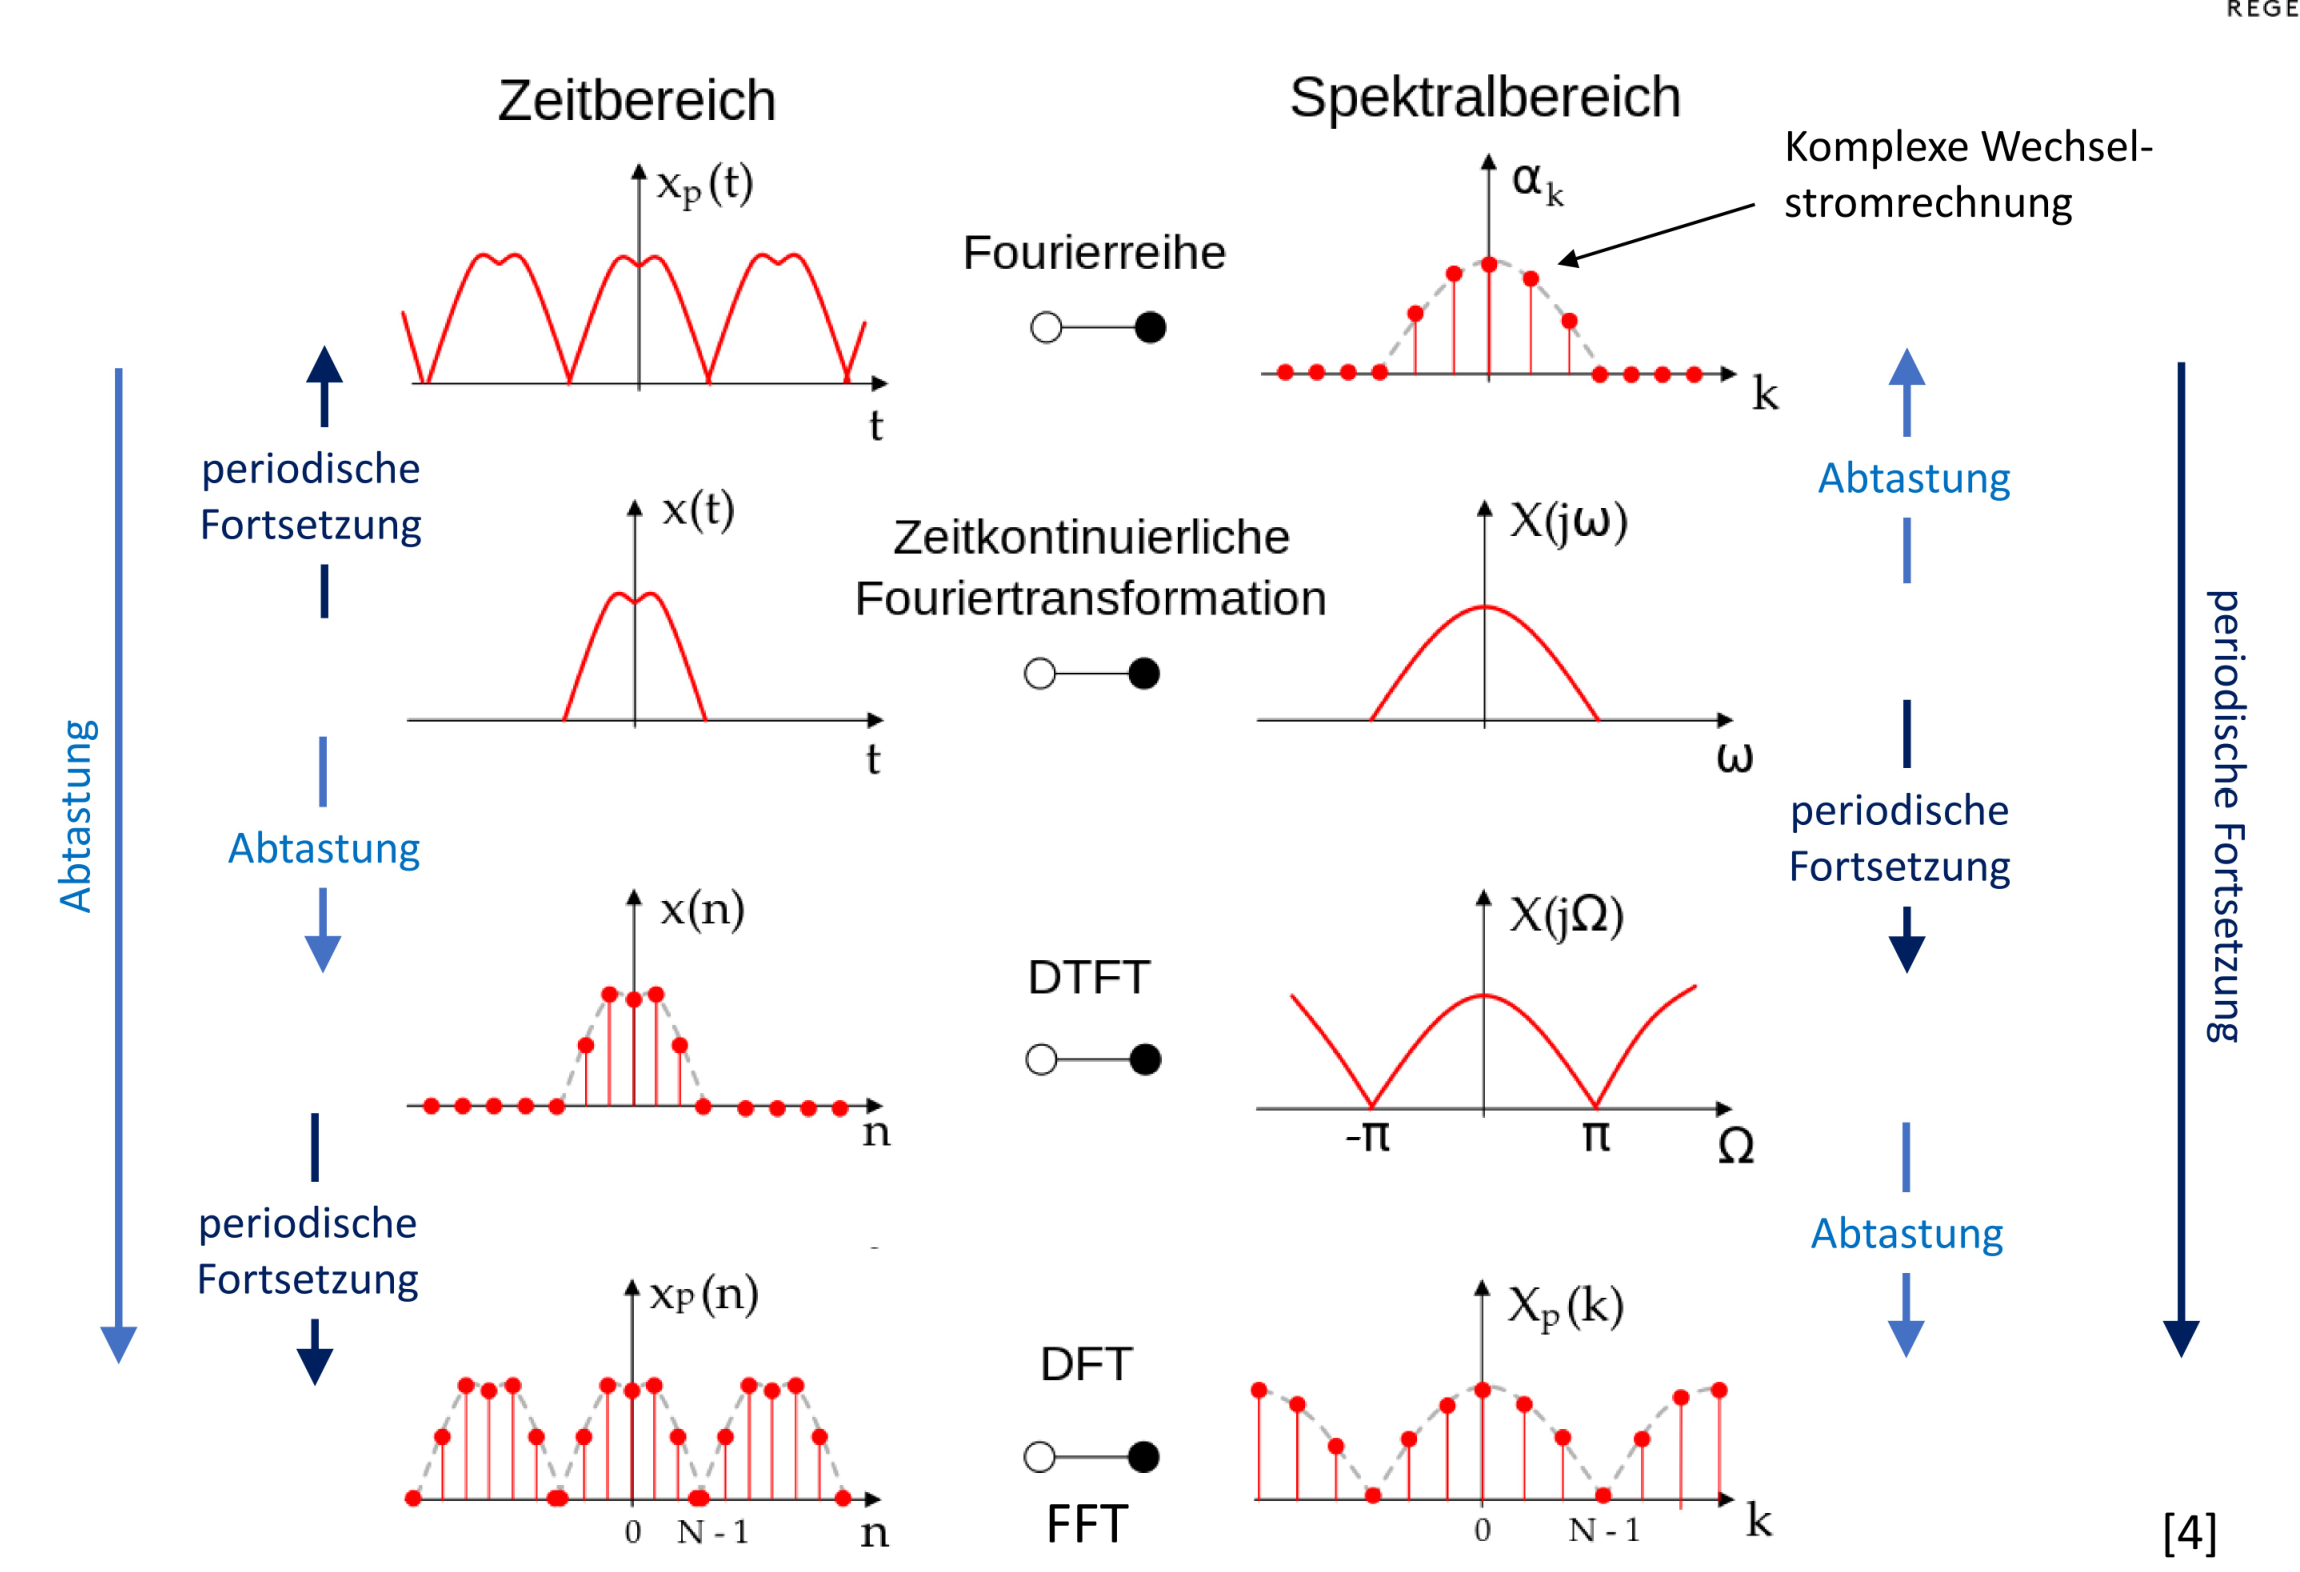

clear,clc
syms A t0 w0 c positive 
syms t w f real

**gaussian pulse modulated sinus signal**

x = A*sin(w0*t).*exp(-(t-t0).^2/(2*c^2))

$$x = A\,{\mathrm{e}}^{-\frac{{\left(t-t_{0}\right)}^{2}}{2\,c^{2}}}\,\sin\left(t\,w_{0}\right)$$

**symbolic fourier transform**

X = simplify(fourier(x,t,w),199);

parameter

T=1;
A=1.5;
t0=0.5;
w0=2*pi*18;
c=0.06;

plot signal in time domain

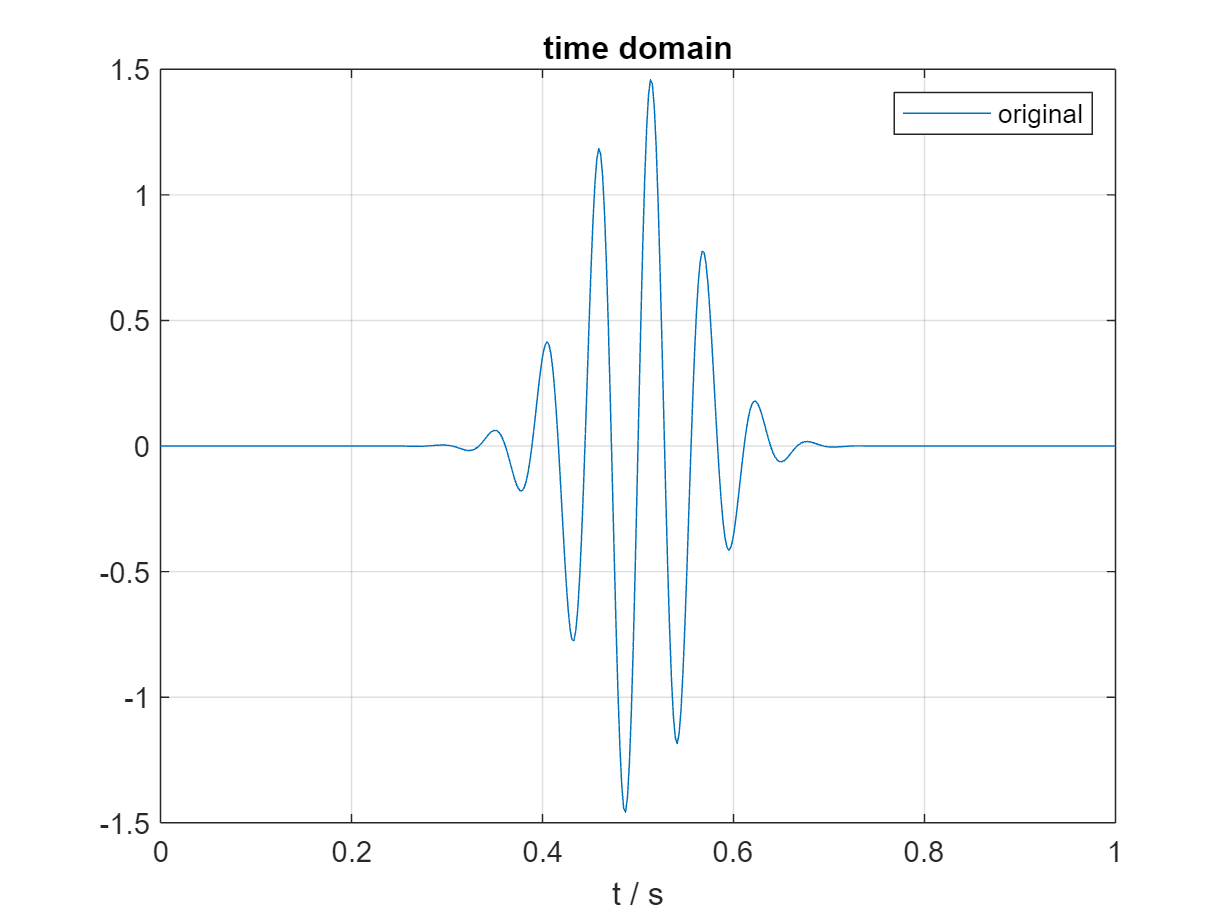

figure(1),clf
t = linspace(0,T,500);
plot(t,eval(x),'DisplayName','original')
hold on, grid on
xlabel('t / s')
title('time domain')
legend

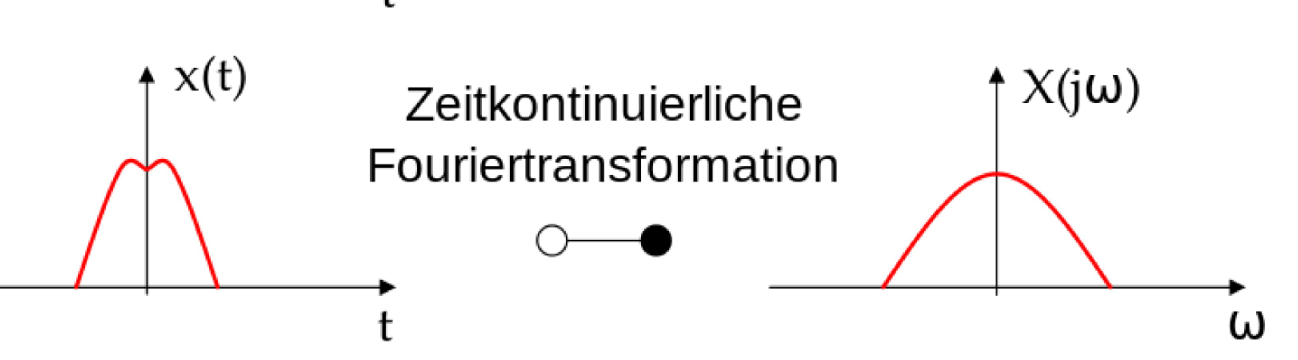

plot spectrum in frequency domain

X

$$X = \sqrt{2}\,A\,c\,\sqrt{\pi }\,\sin\left(t_{0}\,w_{0}-c^{2}\,w\,w_{0}\,\mathrm{i}\right)\,{\mathrm{e}}^{-\frac{c^{2}\,w^{2}}{2}-\frac{c^{2}\,{w_{0}}^{2}}{2}-\mathrm{i}\,t_{0}\,w}$$

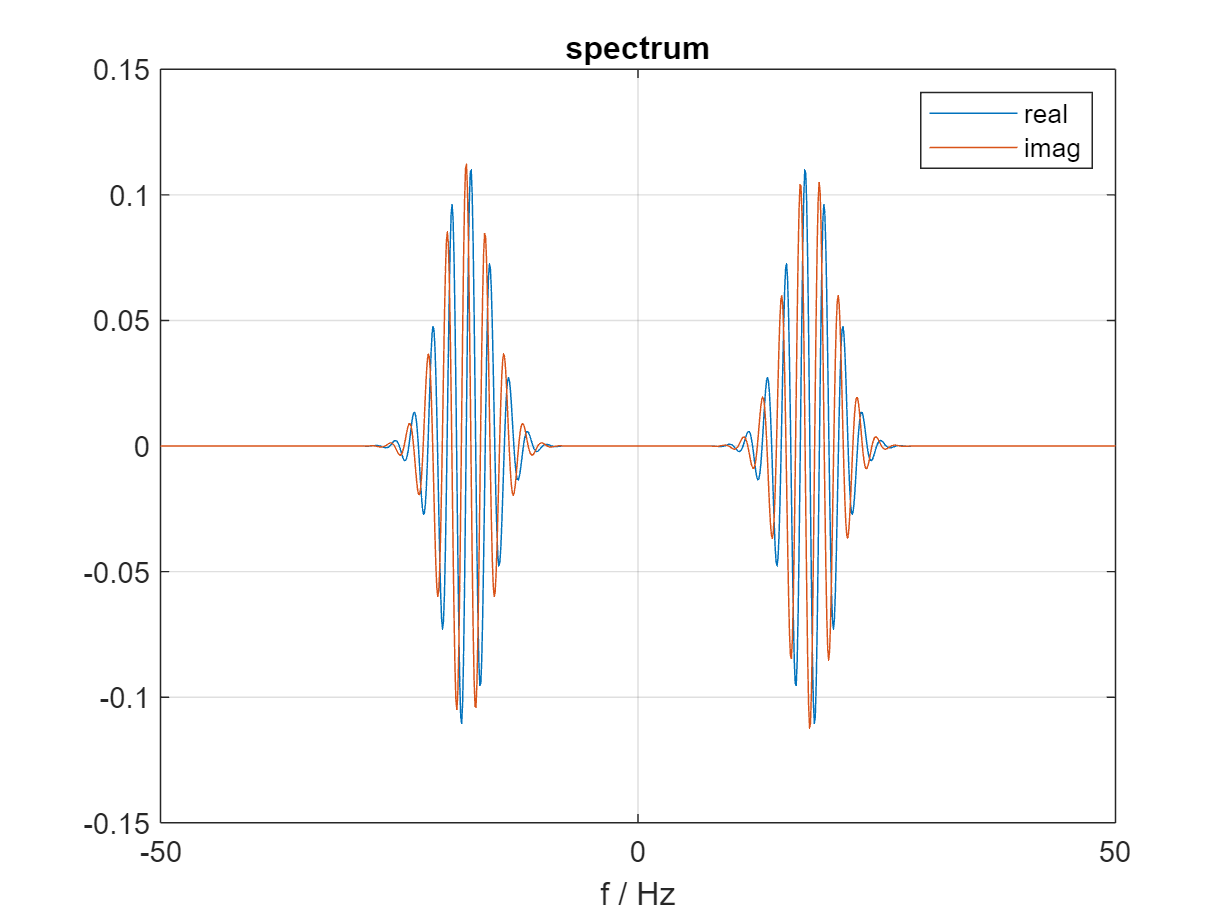

X = subs(X,w,2*pi*f);
figure(2),clf
fmax=50;
f=linspace(-fmax,fmax,1e3);
plot(f,eval(real(X)),'DisplayName','real')
hold on, grid on
plot(f,eval(imag(X)),'DisplayName','imag')
xlabel('f / Hz')
legend
title('spectrum')

### Sample continous spectrum

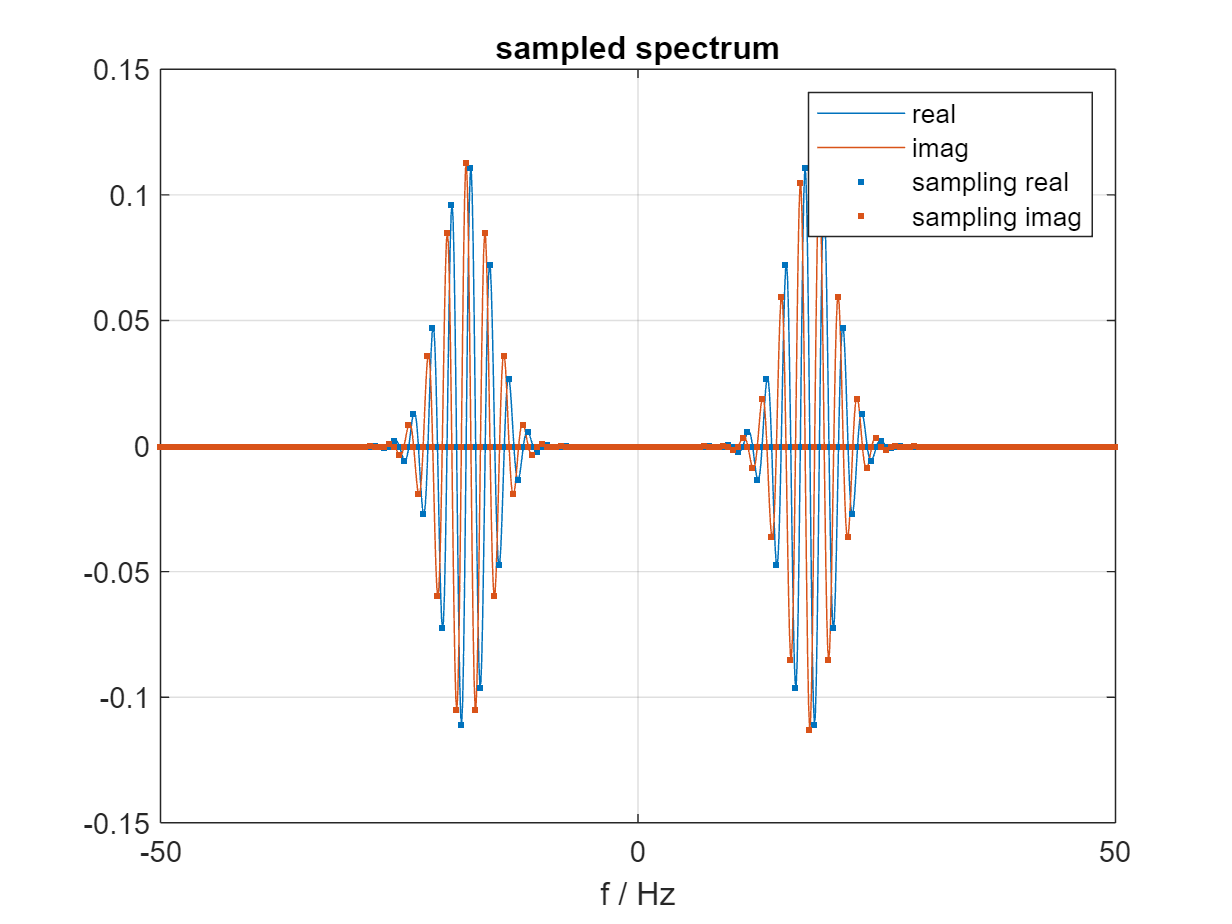

fs=0.5;  % sample frequency determines periodicity T in time domain
T=1/fs;

f=-fmax:fs:fmax;w=2*pi*f;
set(gca,'ColorOrderIndex',1)
plot(f,eval(real(X)),'.','DisplayName', 'sampling real')
hold on, grid on
plot(f,eval(imag(X)),'.','DisplayName', 'sampling imag')
title('sampled spectrum')

###  Fouriersynthesis: discrete nonperiodic spectrum -> continous periodic function

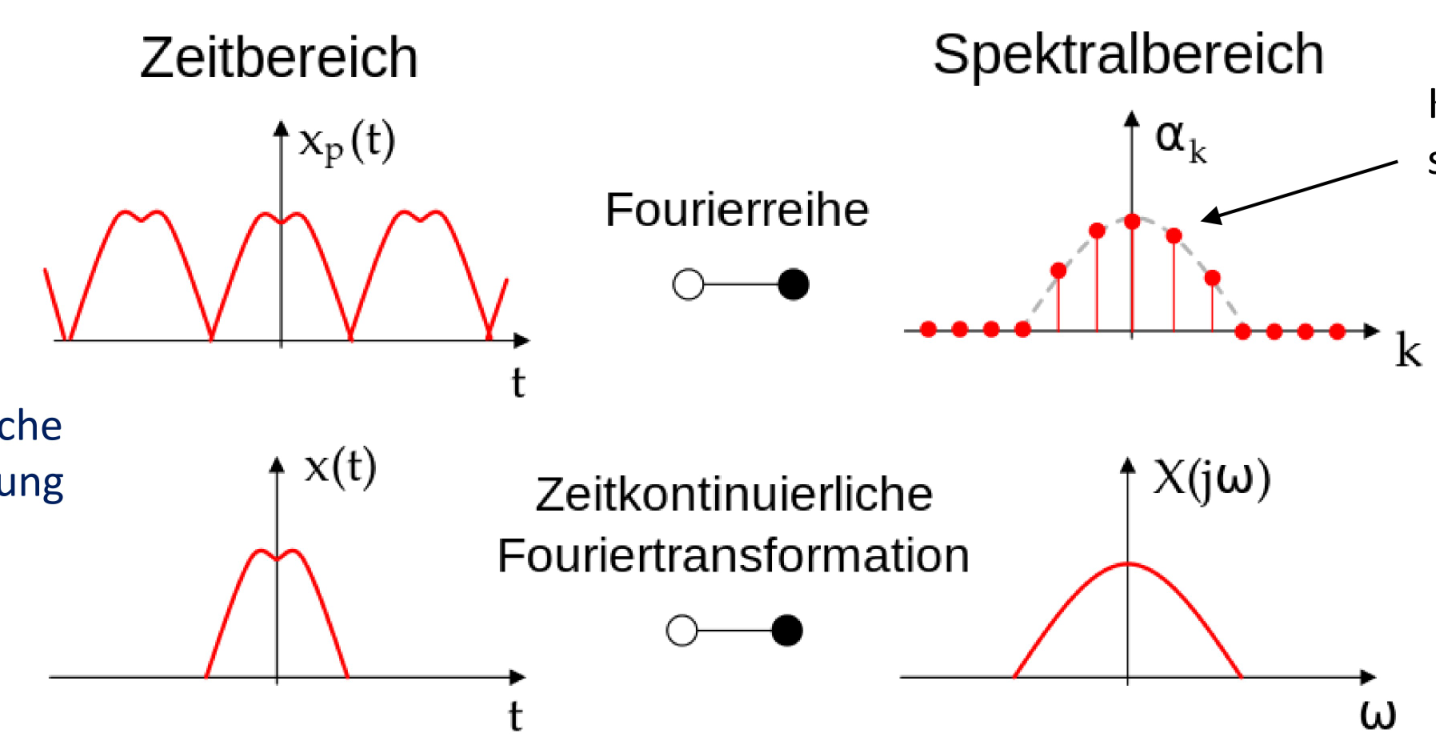

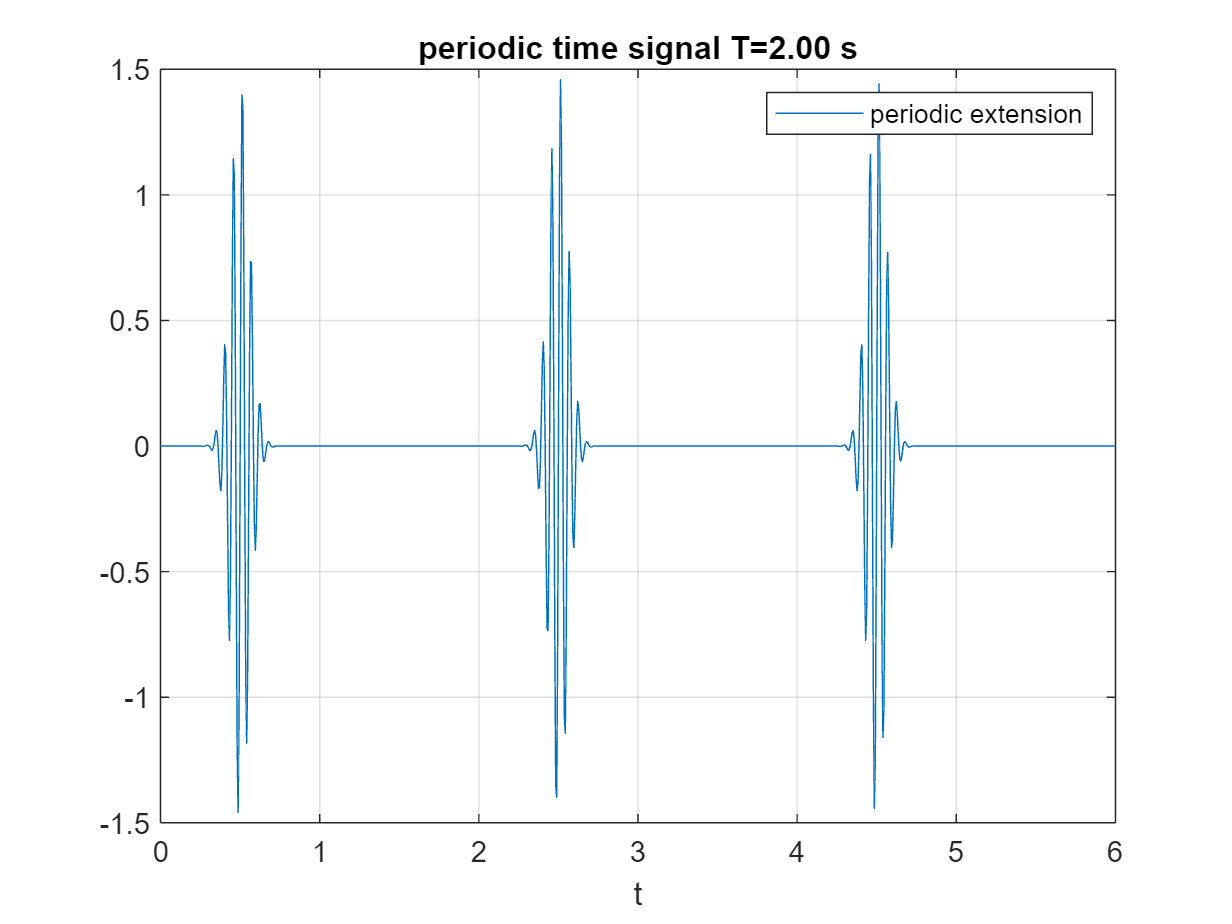

figure(3),clf 
t = linspace(0,3*T,999);
xp=exp(t'*1j*w)*transpose(eval(X))/T;
plot(t,real(xp),'DisplayName','periodic extension')
hold on, grid on
xlabel('t')
title(sprintf('periodic time signal T=%2.2f s',T))
legend

### sample time domain

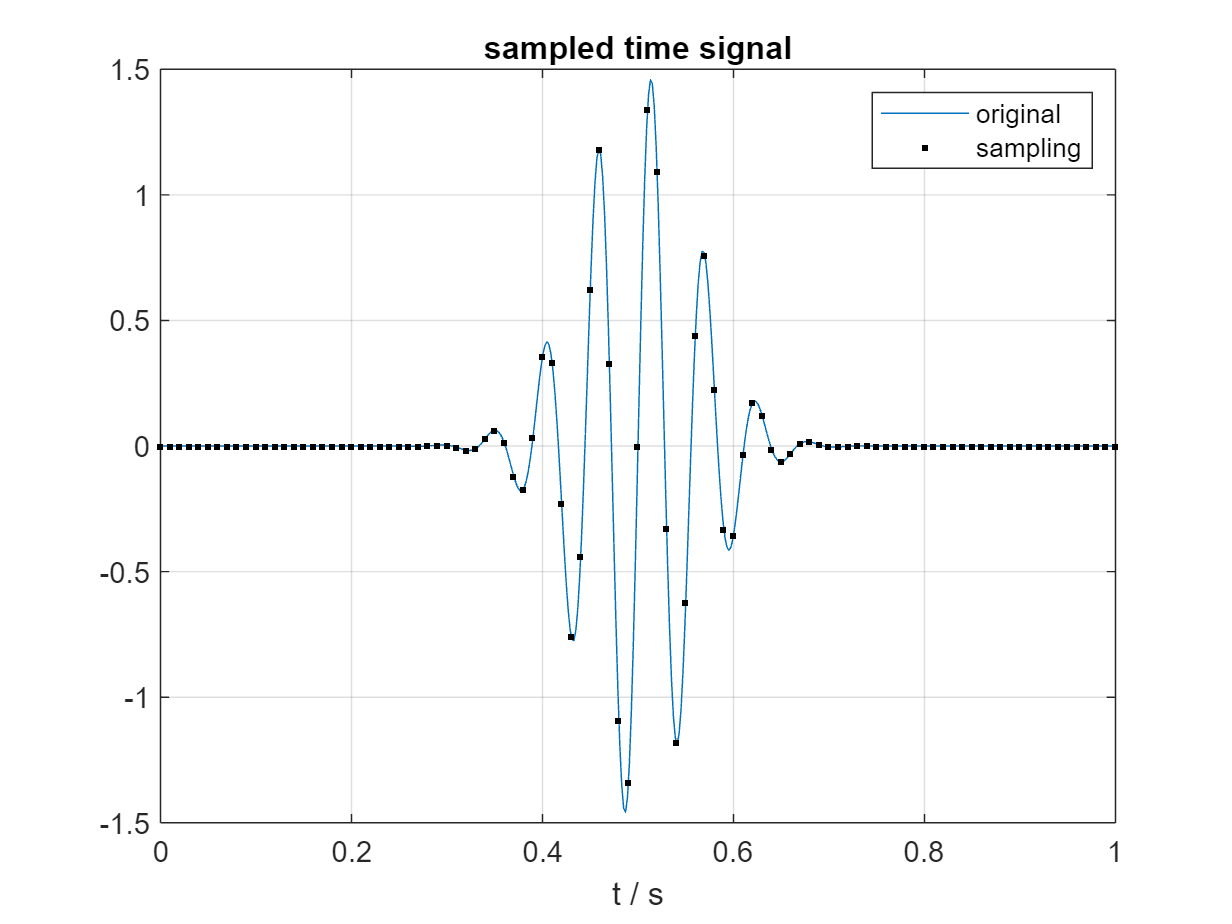

ts=1/100;      % sampling time: at least 2*max_freq to avoid aliasing
t = 0:ts:1;
figure(1)
y=eval(x);
plot(t,y,'k.','DisplayName','sampling')
title('sampled time signal')

### 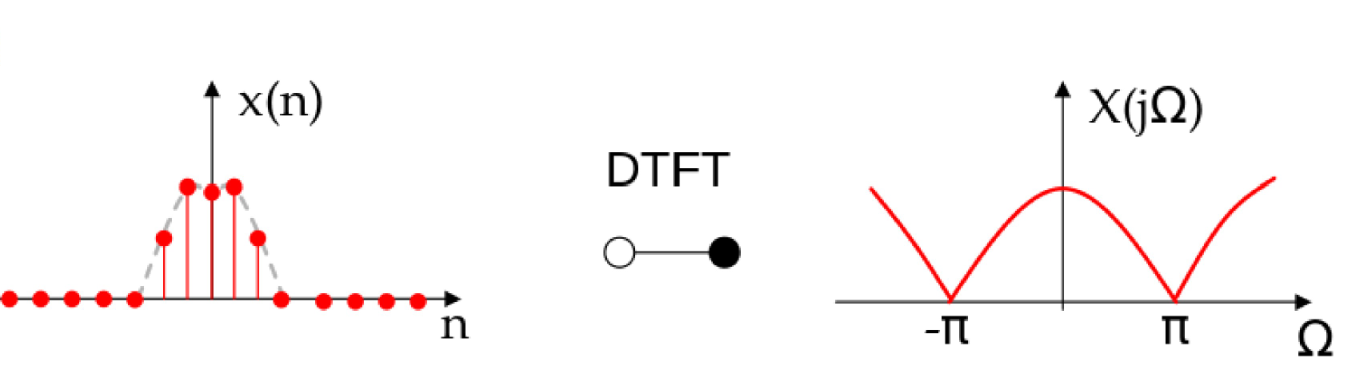

### DTFT: discrete nonperiodic signal -> continous periodic spectrum

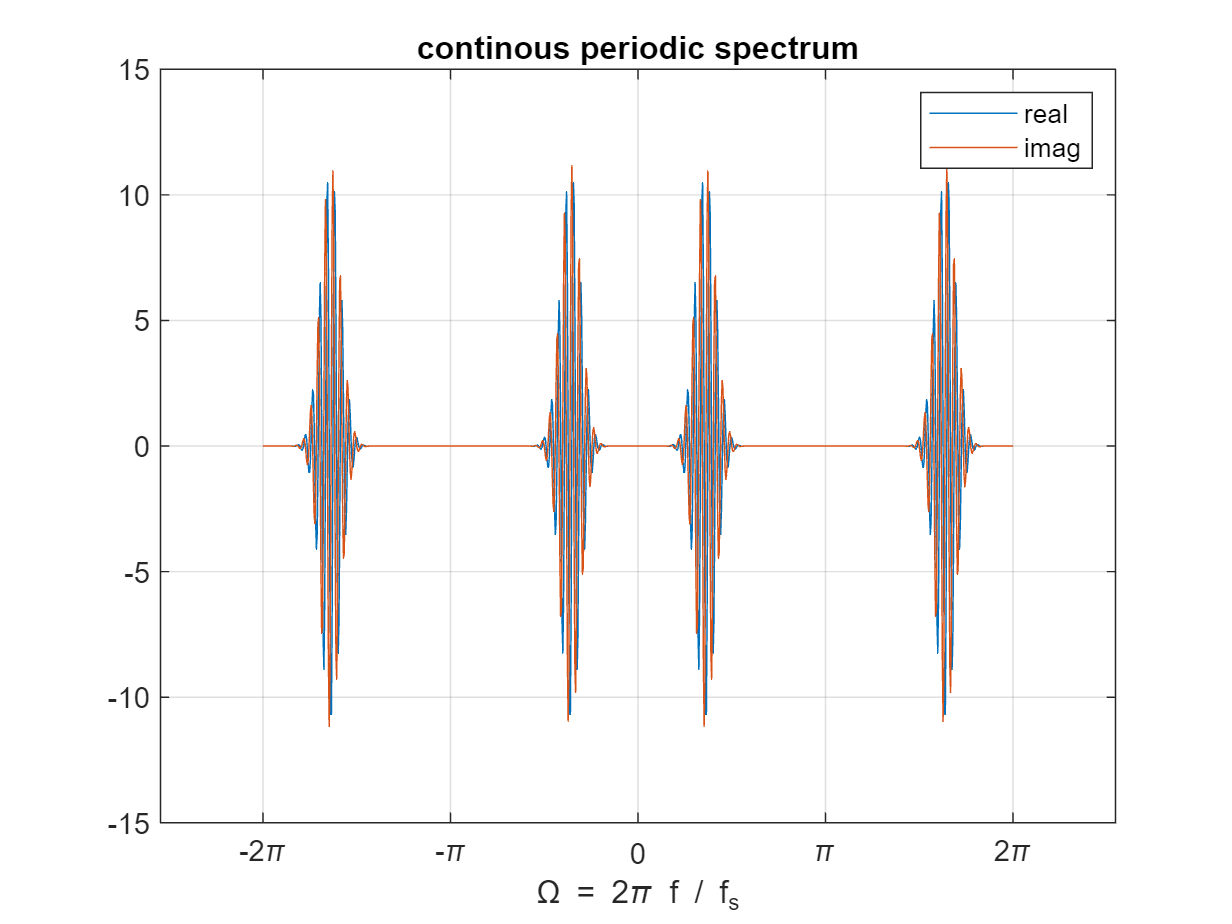

n=1:length(t);
W=linspace(-2*pi,2*pi,999);
Y=exp(-1j*W'*n)*y';

% plot 
figure(4),clf
plot(W,real(Y))
hold on, grid on
plot(W,imag(Y))
xlabel('\Omega = 2\pi f / f_s')
legend('real','imag','AutoUpdate','off');
xticks(-3*pi:pi:3*pi)
set(gca,'XTickLabel',{'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi',})
title('continous periodic spectrum')

### sample periodic time domain

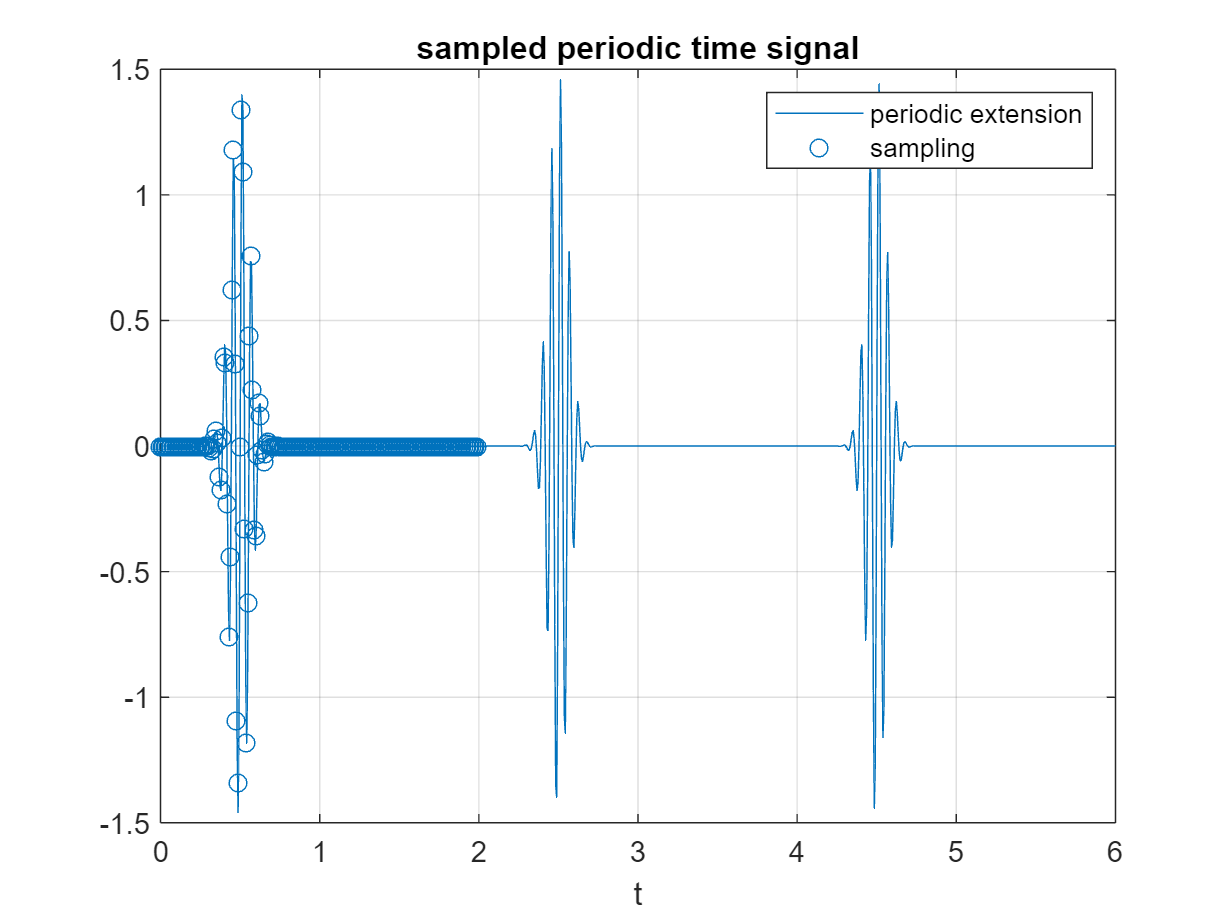

ts=1/100;
t=0:ts:T-ts;
n=length(t);
figure(3)
xp=exp(t'*1j*w)*transpose(eval(X))/T;
set(gca,'ColorOrderIndex',1)
plot(t,real(xp),'o', 'DisplayName','sampling')
title('sampled periodic time signal')

### 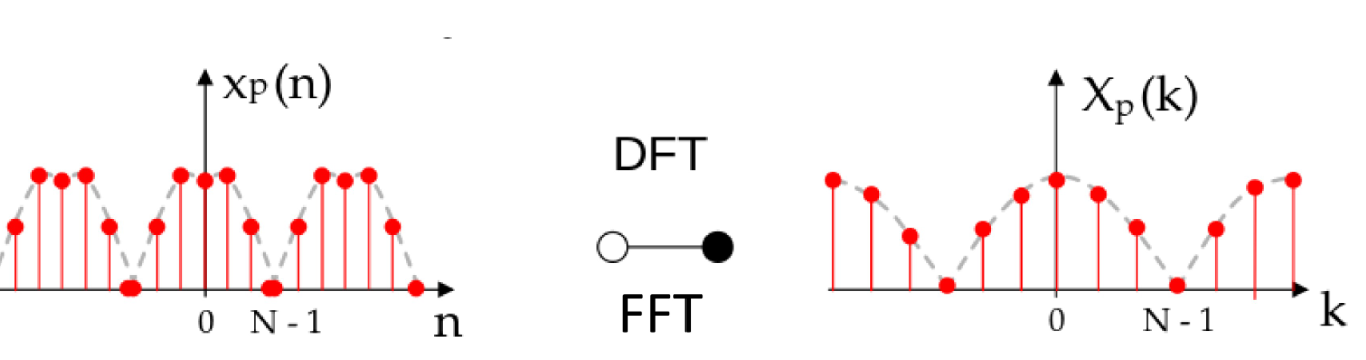

### DFT: discrete periodic signal -> discrete periodic spectrum

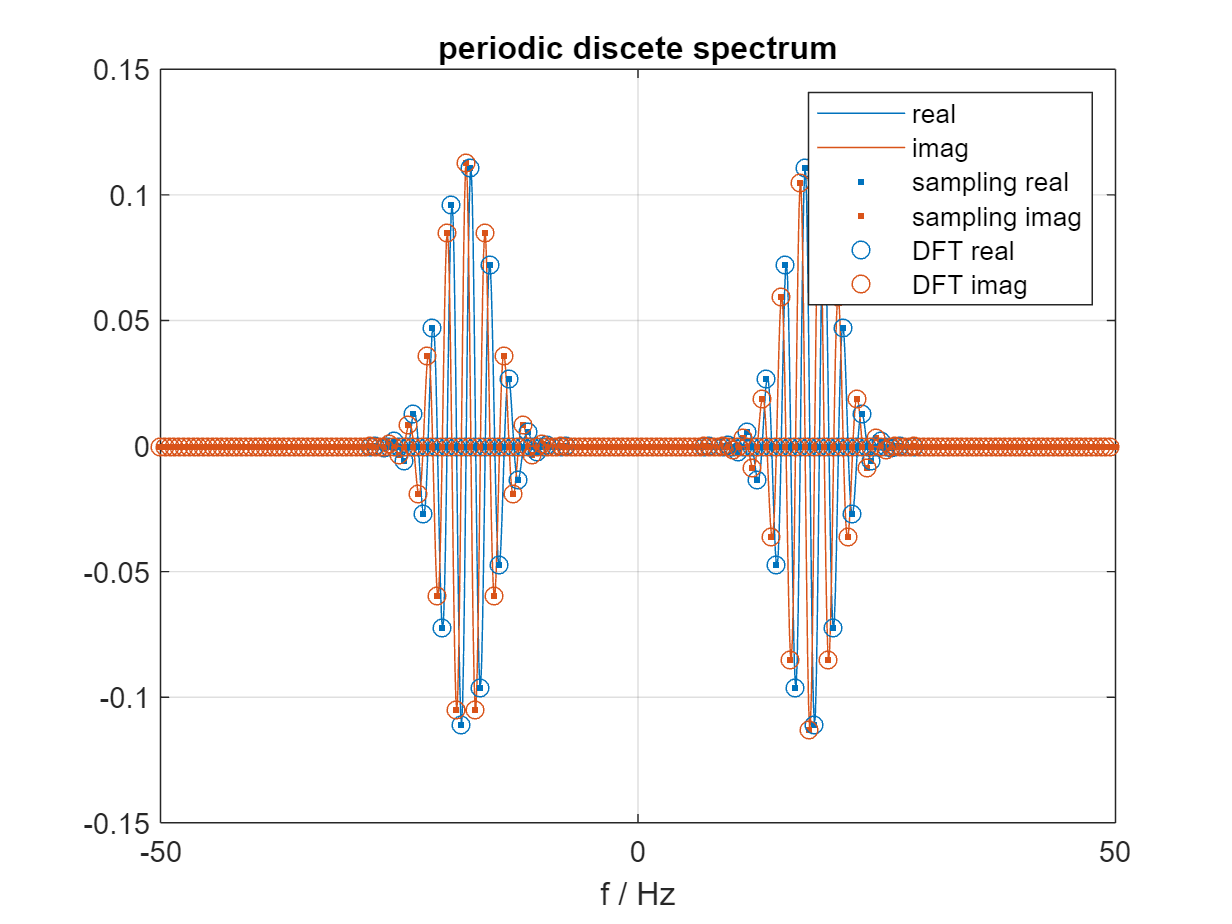

Xp=fft(xp)/n*T;
k=fix(-n/2):fix((n-1)/2);  % n integer samples (fix considers even/odd n) 
freq=k/T;                  % min frequeny (1/T) to max frequency (fs/2)

figure(2)
set(gca,'ColorOrderIndex',1)
plot(freq,real(fftshift(Xp)),'o','DisplayName','DFT real');
hold on, grid on
plot(freq,imag(fftshift(Xp)),'o','DisplayName','DFT imag');
title('periodic discete spectrum')